# Validación de sistema

Comparativa planta no lineal con los datos experimentales. 

clear; clc; close all; 
load("../data/NLsysParams.mat");                        % Importamos los datos de la planta
load("dataFromExperiment", "expY", "expT", "expU"); % Datos experimentales
k_motor_nl = 0.0025;

Extraemos los de la simulacion no lineal

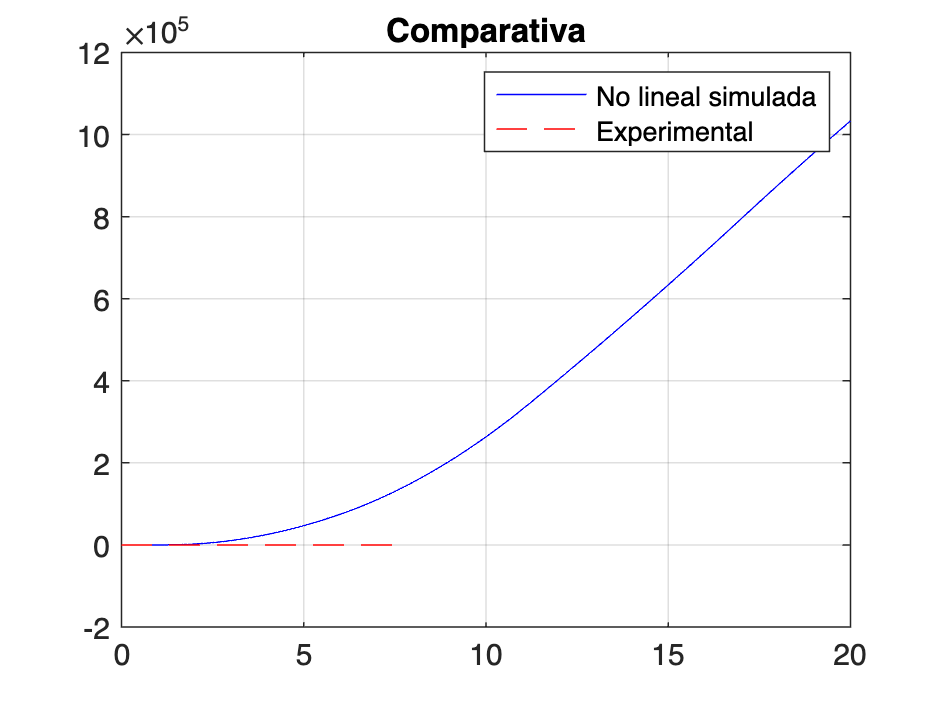

k_motor_nl = 0.0025; % Constante del motor no lineal 
theta_0 = expY(2); 
simout = sim("plantaV1.slx"); % simluacion no lineal 

% Datos de la simulacion 
t = simout.tout; 
y_nl = simout.nl_response.Data; 

plot(t, y_nl, "b-", expT, expY, "r--"); 
legend("No lineal simulada", "Experimental"); grid on; 
title("Comparativa"); 

## Fine tuning

Empezamos a modificar los parámetros de la planta no linea. 

- **Dinámica de Motor**: Zona muerta, Saturación y constante del motor

- **Propiedades Físicas: **Momento de Inercia

% Dinámica del motor 
close all; 
theta_0 = 0

theta_0 = 0

DZ = 5; 
MAX_PWM = 100; 
% k_motor_nl = 0.00111; 
k_motor_nl = 0.00118;  

% Propiedades físicas 
% b =  1.4500e-04;  


%b = 3.9e-4; mu = 2;
% I = mu / (2 * b); 
%I =   12.000e-05 % + (wm  * d1^2 + wcp * d2^2) / 9.81;  

I = 0.4 * 15.000e-05 % + (wm  * d1^2 + wcp * d2^2) / 9.81;  

I = 6.0000e-05

b = 1.237 * (5e-4 / (3 * I))

b = 3.4361



simout = sim("plantaV1.slx", 7.5); 
t = simout.tout; 
y_nl = simout.nl_response.Data; 

% Simulacion con Fine Tuning
subplot(1, 2, 1); 
plot(t, y_nl, "b-", expT, expY + 4.5, "r--", "LineWidth",1.5); 
legend("No lineal simulada", "Experimental", "Location", "northwest"); grid on; 
title("Planta con parámetros iniciales calculados ")
xlabel("tiempo [s]"); 
ylabel("\theta [º]"); 
axis([0, 10, -30, 80])
hold off; 

theta_0 = 0

theta_0 = 0

DZ = 5; 
MAX_PWM = 100; 
% k_motor_nl = 0.00111; 
k_motor_nl = 0.00118;  

% Propiedades físicas 
% b =  1.4500e-04; 

% 3.9e-4; mu = 2;
% I = mu / (2 * b); 
I = 15.000e-05 % + (wm  * d1^2 + wcp * d2^2) / 9.81;  

I = 1.5000e-04

b = 5e-4 / (2 * I)

b = 1.6667

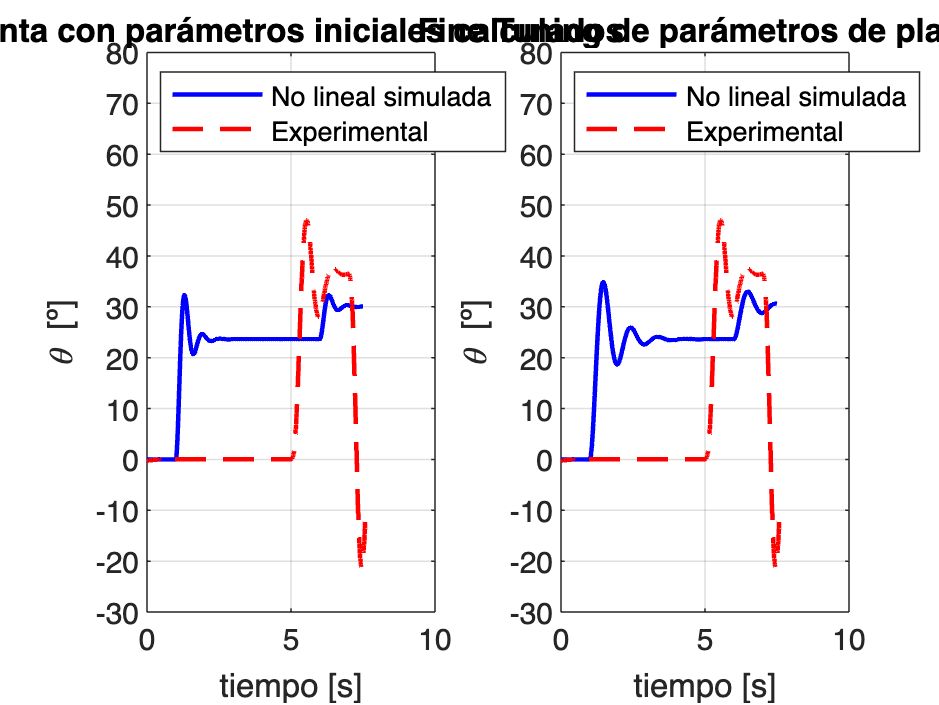


simout = sim("plantaV1.slx", 7.5); 
t = simout.tout; 
y_nl = simout.nl_response.Data; 



subplot(1, 2, 2); 
plot(t, y_nl, "b-", expT, expY + 4.5, "r--", "LineWidth",1.5); 
xlabel("tiempo [s]"); 
ylabel("\theta [º]"); 
legend("No lineal simulada", "Experimental", "Location", "northwest"); grid on; 
title("Fine Tuning de parámetros de planta")
hold off; 

axis([0, 10, -30, 80])

## Señales de referencia

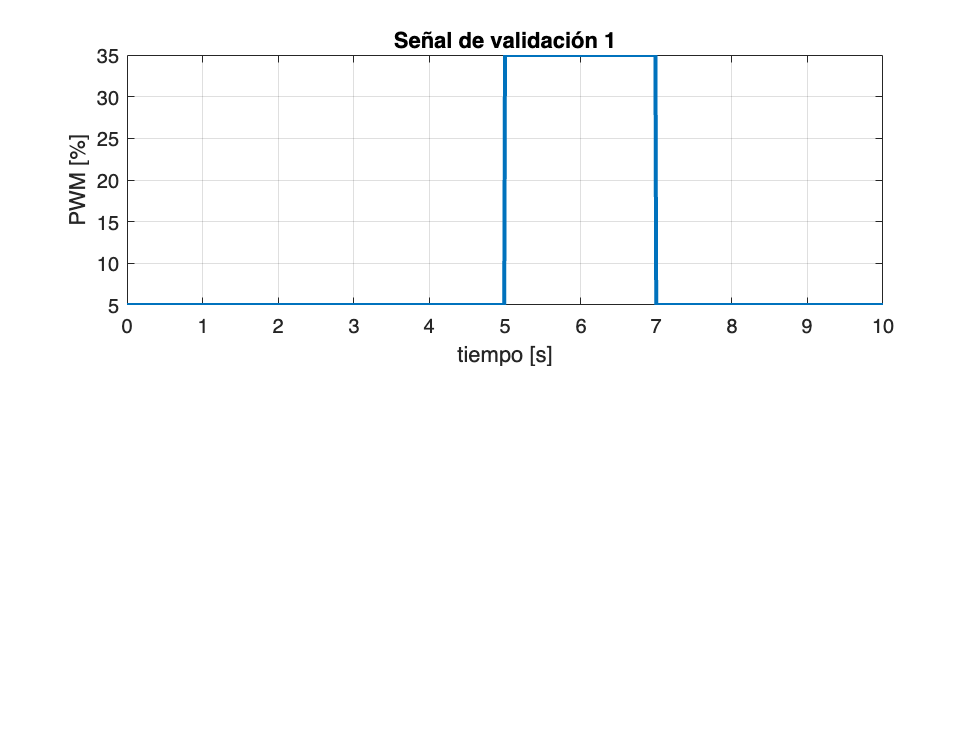

Error using axis>LocSetLimits
Vector must have 4, 6, or 8 elements.

Error in axis (line 114)
                LocSetLimits(ax(j),cur_arg,names);

u = @(t) (t >= 0); 

t = 0:0.01:10; 
x1 = 5 + 30 * u(t - 5) - 30 * u(t - 7); 
x2 = 2 * u(t - 1) + u(t - 3) -  2 * u(t - 5) -  u(t - 8); 

subplot(2, 1, 1); 
plot(t, x1, "LineWidth",2);
grid on;
ylabel("PWM [%]")
xlabel("tiempo [s]")
title("Señal de validación 1")

axis([0 10 -1 ])

subplot(2, 1, 2); 
plot(t, x2, "LineWidth",2);
ylabel("PWM [%]")
xlabel("tiempo [s]")
title("Señal de validación 2")
axis([0 10 -1 4])
grid on;



## Optimización de parámetros

Se define una funcion costo 


$$e\left(x\right)=\int_{t_0 }^{t_f } ||\;f_e \left(x\right)\;-f_s \left(x\right)||\;\textrm{dx}$$


Buscamos minimizar la métrica de error absoluto IAE con un vector de parámetros 

$x={\left\lbrack \beta \;,I,K_m \right\rbrack }^T \;$ a partir de un punto inicial $x_0 =\left\lbrack 1\ldotp 45e-4\;\;\;,\;\;\right\rbrack$

I0 = 5.8e-5;
b0 = 1.45e-4;
K0 = 0.0025;

offset = 0.25; 
resolution = 0.01; 
e_min = 100; 
I_min = I0; 
for I = linspace(I0 * (1 - offset), I0 * (1 + offset), 10)
    simout = sim("plantaV1.slx", 7.5); 
    t = simout.tout; 
    y_nl = simout.nl_response.Data; 

    % metrica 
    e = sum(y_nl - expY)
    if e < e_min
        I_min = I; 
        e_min = e; 
    end 
end 

Arrays have incompatible sizes for this operation.

Related documentation


disp("I_min: " + I_min)
disp("e_min: " + e_min)

## Comparativa con constante de motor

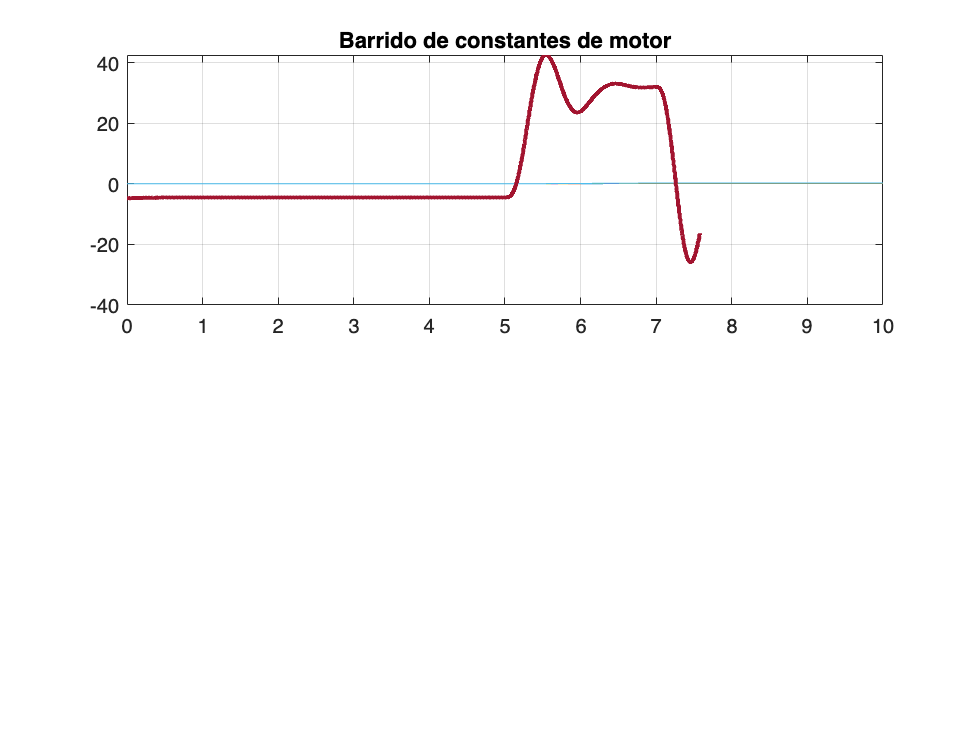

DZ = 5.6; 
MAX_PWM = 100; 
k_motor_nl = 0.00111; 
% k_motor_nl = 0.00090; 


for k_motor_nl = linspace(0.0005, 0.00120, 6)
    simout = sim("plantaV1.slx"); 
    
    t = simout.tout; 
    y_nl = simout.nl_response.Data; 
    
    plot(t, y_nl); 
    hold on; 

end 
hold off; grid on; 
hold on; 
plot(expT, expY, 'LineWidth', 2)
title("Barrido de constantes de motor")

% legend("No lineal simulada", "Experimental"); grid on; 

## Accion de control

Se hace una comparativa de las acciones de control experimentales y reales

   simout = sim("plantaV1.slx"); 
DZ = 3; 
t = simout.tout; 
u_nl = simout.nl_action.Data; 


figure(); 
plot(expT, expU * k_motor_nl, t , u_nl, "r--" , "LineWidth", 2); 
legend("exp", "sim")
title("Comparativas de accion de Control Experimental vs Simulada")


